# 双变量及三变量映射图表的MATLAB绘制

注：mlx文件内的figure不能交互

请尊重原创劳动成果

转载请注明本文链接[MATLAB | 全网唯一！双变量及三变量映射图表的MATLAB绘制 (qq.com)](https://mp.weixin.qq.com/s/Zm_lE6ANPCjT3d6Ahksczw)

及文章作者：slandarer

## 双变量映射图表

**输入输出说明**

需要A,B两个完全相同大小的数值矩阵，通过

的格式调用双变量映射图绘制工具函数，返回值为一个`CMapData`RGB颜色数组，用于给图形对象赋予颜色，以及一个`CMapHdl`图例。

**基本使用**

这里第一个例子是一个网格数据,`multi2_3.mat`中存储着变量`X1`,`X2`,`A`,`B`,`C`,这里只用AB数据，分别是当前格点属于类A和B的概率，简单编写函数如下：

close all
multiData=load('multi2_3.mat');
X1=multiData.X1;
X2=multiData.X2;
A=multiData.A;
B=multiData.B;

% 先绘制一个没有赋予颜色的图形
surfHdl1=surf(X1,X2,zeros(size(X1)),'EdgeColor','none');
hold on;view(2);axis tight

% 调用工具函数生成图例和映射表
[CMapData,CMapHdl]=multiVarMap2(A,B); 

  @author : slandarer
  公众号  : slandarer随笔
  知乎    : hikari



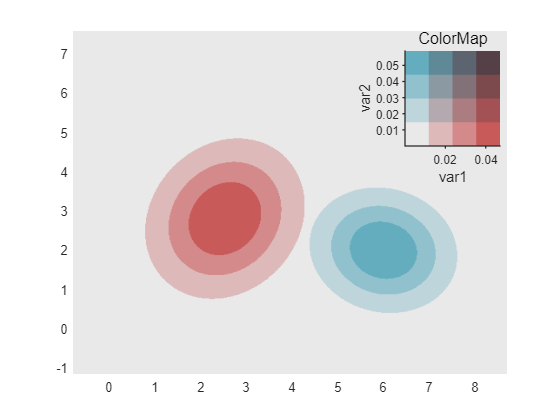

set(surfHdl1,'CData',CMapData);

**颜色划分**

上面每个变量颜色划分了四段，我们可以调整`pieceNum`属性划分更多段颜色，例如分成8段：

close all
surfHdl2=surf(X1,X2,zeros(size(X1)),'EdgeColor','none');
hold on;view(2);axis tight
% 调用工具函数生成图例和映射表
[CMapData,CMapHdl]=multiVarMap2(A,B,'pieceNum',8);

  @author : slandarer
  公众号  : slandarer随笔
  知乎    : hikari



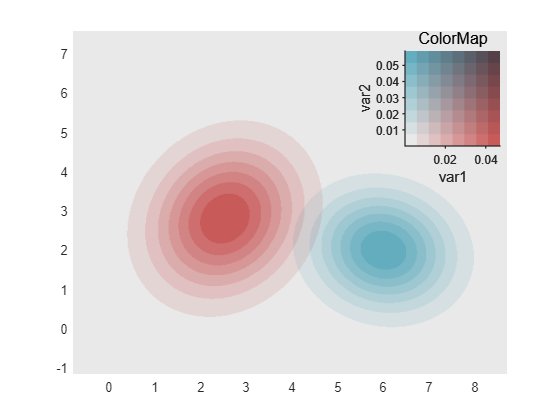

set(surfHdl2,'CData',CMapData);

**其他配色**

可以调整`colorList`属性调整配色，需要4x3大小的RGB数组，分别代表左下，右下，左上，右上的颜色，当然函数内置了12种默认配色，通过1-12的编号调用

close all
surfHdl3=surf(X1,X2,zeros(size(X1)),'EdgeColor','none');
hold on;view(2);axis tight
% 调用工具函数生成图例和映射表
[CMapData,CMapHdl]=multiVarMap2(A,B,'pieceNum',8,'colorList',10); 

  @author : slandarer
  公众号  : slandarer随笔
  知乎    : hikari



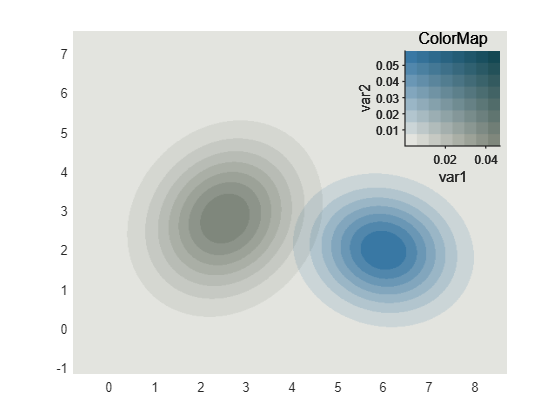

set(surfHdl3,'CData',CMapData);

**修改变量名和标题**

close all
surfHdl4=surf(X1,X2,zeros(size(X1)),'EdgeColor','none');
hold on;view(2);axis tight

% 调用工具函数生成图例和映射表
[CMapData,CMapHdl]=multiVarMap2(A,B,'pieceNum',8,'colorList',10,'title','XXXXX','varName',{'AAAAA','BBBBB'}); 

  @author : slandarer
  公众号  : slandarer随笔
  知乎    : hikari



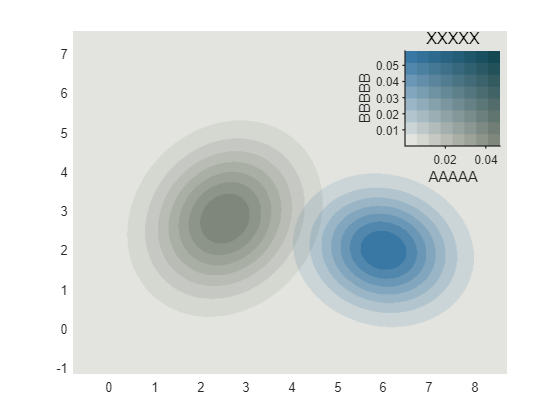

set(surfHdl4,'CData',CMapData);

**三维绘图**

close all
% 先绘制一个没有赋予颜色的图形
surfHdl5=surf(X1,X2,max(A,B),'EdgeColor','none');
hold on;view(3);axis tight

% 调用工具函数生成图例和映射表
[CMapData,CMapHdl]=multiVarMap2(A,B,'colorList',10,'pieceNum',8);

  @author : slandarer
  公众号  : slandarer随笔
  知乎    : hikari



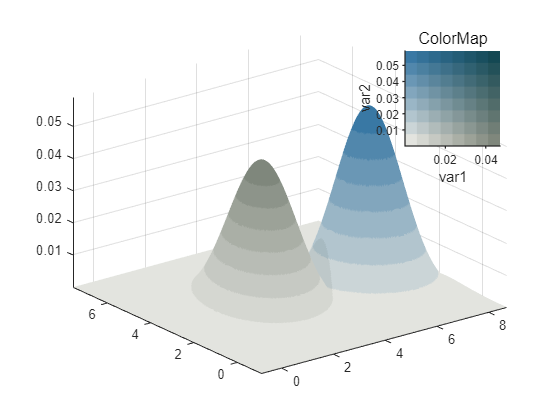

set(surfHdl5,'CData',CMapData);

**地图绘制**

展示mapping toolbox绘制的图双变量映射，因此需要提前安装mapping toolbox工具箱，当然其他地图绘制工具箱绘制的图用本文的双变量映射也差不多，以下内容懒得收集数据，于是随便生成了一些数据：

close all
axm=usamap("conus");

states=shaperead("usastatelo.shp",'UseGeoCoords',true);
% 俩州离太远画不开，不要
for i=length(states):-1:1
    if states(i).Name=="Alaska"||states(i).Name=="Hawaii"
        states(i)=[];
    end
end

faceColors=makesymbolspec('Polygon',{'INDEX',[1 numel(states)],'FaceColor',...
  polcmap(numel(states))});
usaMap=geoshow(states, 'DisplayType','polygon','SymbolSpec', faceColors);

% 不想去收集数据了，随便生成点随机数
A=rand(numel(states),1);
B=rand(numel(states),1);

% 调用工具函数生成图例和映射表
[CMapData,CMapHdl1]=multiVarMap2(A,B,'colorList',11,'pieceNum',8);

  @author : slandarer
  公众号  : slandarer随笔
  知乎    : hikari



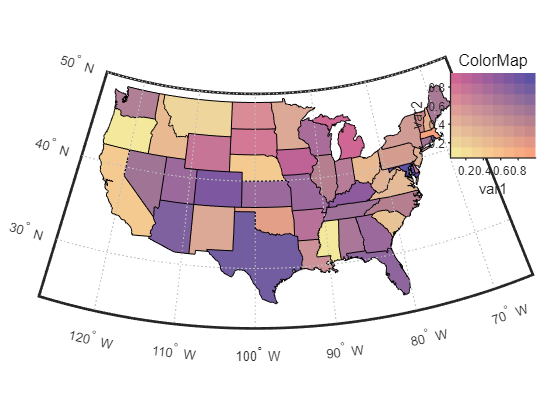

% 循环修改每个州颜色
for i=1:length(usaMap.Children)
    usaMap.Children(i).FaceColor=[CMapData(i,1,1),CMapData(i,1,2),CMapData(i,1,3)];
end

**气泡图绘制**

close all
x=1:20;
y=rand(1,20);
sz=rand(1,20);
BC=bubblechart(x,y,sz); 

% 不想去收集数据了，随便生成点随机数
A=rand(1,20);
B=rand(1,20);

% 调用工具函数生成图例和映射表
[CMapData,CMapHdl1]=multiVarMap2(A,B,'colorList',10,'pieceNum',8);

  @author : slandarer
  公众号  : slandarer随笔
  知乎    : hikari



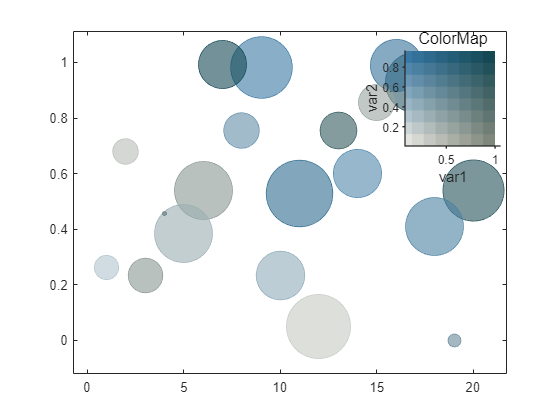

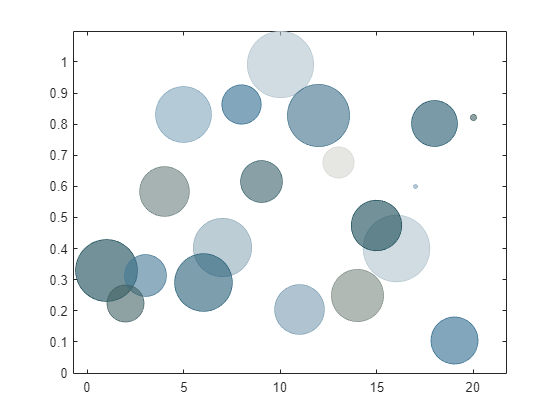

BC.CData=[CMapData(:,:,1)',CMapData(:,:,2)',CMapData(:,:,3)'];